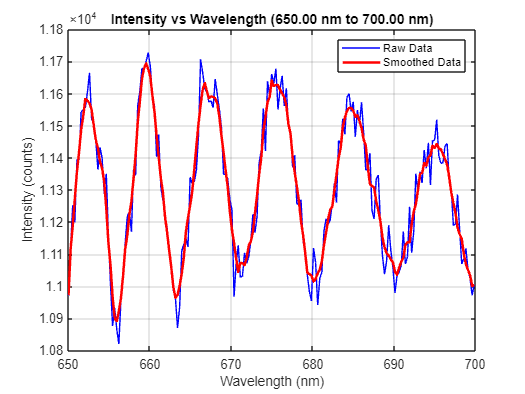

% Define the file name
filename = "C:\Users\jerub\Desktop\ECCE\Courses-Modules\Msc Project\FIND THE BREAK TIME\without and load or strain_HR4C58731_00001.txt";
% Read the data from the file
data = readmatrix(filename);

% Extract the wavelength and intensity columns
wavelength = data(:, 1);
intensity = data(:, 2);

% Define the desired wavelength range (e.g., 720 nm to 740 nm)
wavelength_min = 650; % Change this to the desired minimum wavelength
wavelength_max = 700; % Change this to the desired maximum wavelength

% Find the indices of the wavelengths within the desired range
indices = (wavelength >= wavelength_min) & (wavelength <= wavelength_max);

% Extract the corresponding wavelength and intensity values
wavelength_range = wavelength(indices);
intensity_range = intensity(indices);

% Smooth the intensity data within the range
smoothed_intensity_range = smooth(intensity_range);

% Find the maximum intensity and the corresponding wavelength for raw data
[max_intensity_raw, max_index_raw] = max(intensity_range);
max_wavelength_raw = wavelength_range(max_index_raw);

% Find the maximum intensity and the corresponding wavelength for smoothed data
[max_intensity_smooth, max_index_smooth] = max(smoothed_intensity_range);
max_wavelength_smooth = wavelength_range(max_index_smooth);

% Plot the raw and smoothed intensity values within the desired wavelength range
figure;
plot(wavelength_range, intensity_range, 'b-', 'DisplayName', 'Raw Data');
hold on;
plot(wavelength_range, smoothed_intensity_range, 'r-', 'LineWidth', 2, 'DisplayName', 'Smoothed Data');



xlabel('Wavelength (nm)');
ylabel('Intensity (counts)');
title(sprintf('Intensity vs Wavelength (%.2f nm to %.2f nm)', wavelength_min, wavelength_max));
legend;
grid on;